# Stima con multisinusoidi su SCARA. 

Modello MIMO

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi
st=1e-3;
addpath(['..',filesep,'modelli']) %aggiunge al path la cartella modelli (che deve essere nella cartella superiore)

robot=getScaraRobot;


hm=[2 2];
cm=[0 0];
dt=1e-3;
umax=[500; 500];


k=10000*[1 1];
h=2*[1 1];
Jm=[5 5];
system=RoboticSystem(dt,robot,hm,cm,umax,true,Jm,k,h);
system.setForwardDynamics(@fdCodegen_mex)

cs=ControlledSystem(system);

use_close_loop=true;
if (use_close_loop)
    controller=SimpleScaraController(st);
    cs.setController(controller);
end

## Identificazione

Definisco l'azione di controllo come una somma di portante e una sommatoria di sinusoidi. Le sinusoidi devono avere frequenza multipla di quella della portante.

#### Portante

omega_portante=1;
ampiezza_portante=0;
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Multisinusoidi:

Scelgo le sinusoidi come un vettore logaritmicamente spaziato (potrei infittirlo nelle zone di interesse)

w0=0.5;
w1=1500;
omega=logspace(log10(w0),log10(w1),60)';

arrotondo a dei multipli della portante

omega=round(omega/omega_portante)*omega_portante; % arrotondo per avere le omega multiple della portante

Rimuovo duplicati

omega=unique(omega); %scarto eventuali doppioni

Credo il segnale come somma di sinusoidi (qui suppongo ampiezza costante per ogni pulsazione, nulla mi impedisce di fare diversamente)

input_names=system.getInputName;
output_names=system.getOutputName;

multisine_signal=zeros(length(t),length(input_names));
exciting_signal=zeros(length(t),system.getInputNumber);
reference=zeros(length(t),system.getOutputNumber);
max_applitude=2;

n_tests=4;%length(input_names);
for itest=1:n_tests
    for ii=1:length(input_names)
        for idx=1:length(omega)
            fase=rand*2*pi;
            ampiezza_relativa=0.5+0.5*rand; % fra 0.5 e 1
            coeff_sin=sin(fase)*ampiezza_relativa;
            coeff_cos=cos(fase)*ampiezza_relativa;
            multisine_signal(:,ii)=multisine_signal(:,ii)+coeff_sin*sin(omega(idx)*t)+coeff_cos*cos(omega(idx)*t);
        end

Impongo che l'ampiezza del segnale sia quella desiderata

        multisine_signal(:,ii)=multisine_signal(:,ii)/max(multisine_signal(:,ii))*max_applitude;
        exciting_signal(:,ii)=portante+ multisine_signal(:,ii);
    end

Simulo il sistema


    cs.initialize
    for idx=1:length(t)
        if use_close_loop
            [process_output(idx,:),control_action(idx,:),t(idx,1)]=cs.step(reference(idx,:)',exciting_signal(idx,:)');
        else
            [process_output(idx,:),t(idx,1)]=cs.openloop(exciting_signal(idx,:));
            control_action(idx,:)=exciting_signal(idx,:);
        end
    end

Calcolo i coefficienti di Fourier dell'uscita

    for io=1:length(output_names)
        process_output_coef(:,io,itest)=fourierCoefficients(t,process_output(:,io),omega_portante,omega);
    end
    for ii=1:length(input_names)
        control_action_coef(:,ii,itest)=fourierCoefficients(t,control_action(:,ii),omega_portante,omega);
    end
    ident{itest}=iddata(process_output,control_action,dt);
end

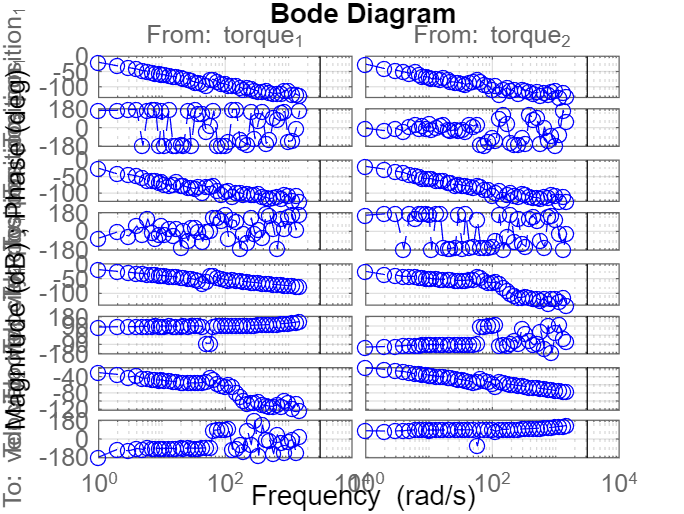

for iw=1:length(omega) % per tutte le omega
    for itest=1:length(input_names)
        Y(:,itest)=process_output_coef(iw,:,itest)';
        U(:,itest)=control_action_coef(iw,:,itest)';
    end
    fr_data(:,:,iw)=Y/U;
end
freq_resp=idfrd(fr_data,omega,st);
freq_resp.InputName=input_names;
freq_resp.OutputName=output_names;

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
figure
bodeplot(freq_resp,'--o', bode_opts);
grid on
hold on

Stima modello 

peso=ones(length(freq_resp.Frequency),1);
wpeso0=2;
wpeso1=300;
peso(freq_resp.Frequency<wpeso0)=1e-5;
peso(freq_resp.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
md = ssest(freq_resp,4,'Ts',st,opts);

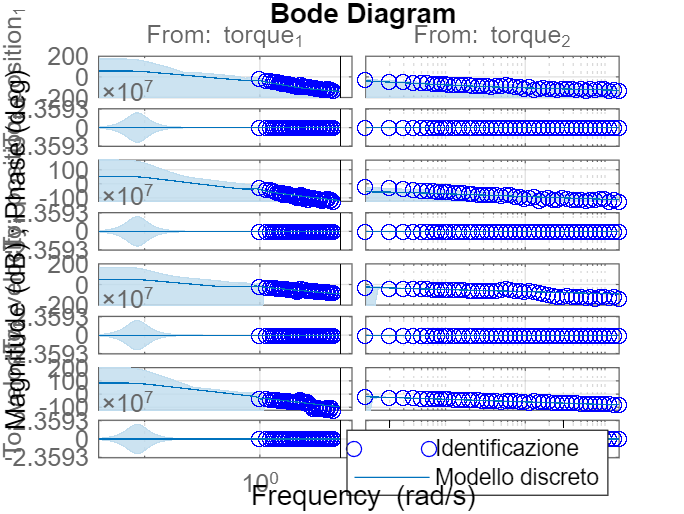

figure


bode_handle=bodeplot(freq_resp,'o', bode_opts);
showConfidence(bode_handle,3)
hold on
bodeplot(md, bode_opts)
xlim([omega(1) omega(end)])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
grid on
legend('Identificazione','Modello discreto')
grid on

**Nota**: i poli in z=1 (o s=0) per errore numerico potrebbero risultare instabili.